# **Lab 2 - Nonlinear Regression **

# Submitted by: Priyanshu Rawat

%% Given function 
syms a x y 
f(x) = log(a*x);
fprintf('Given function:\nf(x) = %s', f(x))

Given function:
f(x) = log(a*x)

%% Error function
E = (y - log(a*x))^2;
fprintf('Error function:\nE = %s', E)

Error function:
E = (y - log(a*x))^2

%% Taking derivative of the square of the error function w.r.t. `a`
dE = diff(E, a);
fprintf('Derivative of the error function:\ndE^2/da = %s', dE)

Derivative of the residual function:
dE^2/da = -(2*(y - log(a*x)))/a

%% Using root finding approach to find `a` 
fa = dE;
fprintf('Function to perform root finding:\nf(a) = %s', fa)

Function to perform root finding:
f(a) = -(2*(y - log(a*x)))/a

%% Taking derivative of f(a) 
dfa = diff(fa, a);
fprintf('Derivative of f(a):\ndf(a)/da = %s', dfa)

Derivative of f(a):
df(a)/da = 2/a^2 + (2*(y - log(a*x)))/a^2

# Nonlinear Regression fit: `log-data-A`

%% Loading log-data-A
data_A = importdata('log-data-A.txt');
Xa = data_A(:,1);
Ya = data_A(:,2);

#### Guess-1: Taking initial value of `a` = 1

%% Initial guess
a0 = 1;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xa)
        sum_fa = sum_fa + (-(2*(Ya(i) - log(a0*Xa(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Ya(i) - log(a0*Xa(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 6.711359e+00

Total number of iterations until convergence: 9

#### Guess-2: Taking initial value of `a` = 2

%% Initial guess
a0 = 2;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xa)
        sum_fa = sum_fa + (-(2*(Ya(i) - log(a0*Xa(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Ya(i) - log(a0*Xa(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 6.711359e+00

Total number of iterations until convergence: 8

#### Guess-3: Taking initial value of `a` = 5

%% Initial guess
a0 = 5;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xa)
        sum_fa = sum_fa + (-(2*(Ya(i) - log(a0*Xa(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Ya(i) - log(a0*Xa(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 6.711359e+00

Total number of iterations until convergence: 5

#### Guess-4: Taking initial value of `a` = 8.5

%% Initial guess
a0 = 8.5;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xa)
        sum_fa = sum_fa + (-(2*(Ya(i) - log(a0*Xa(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Ya(i) - log(a0*Xa(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 6.711359e+00

Total number of iterations until convergence: 6

### Plotting the model and the data points in log-data-A

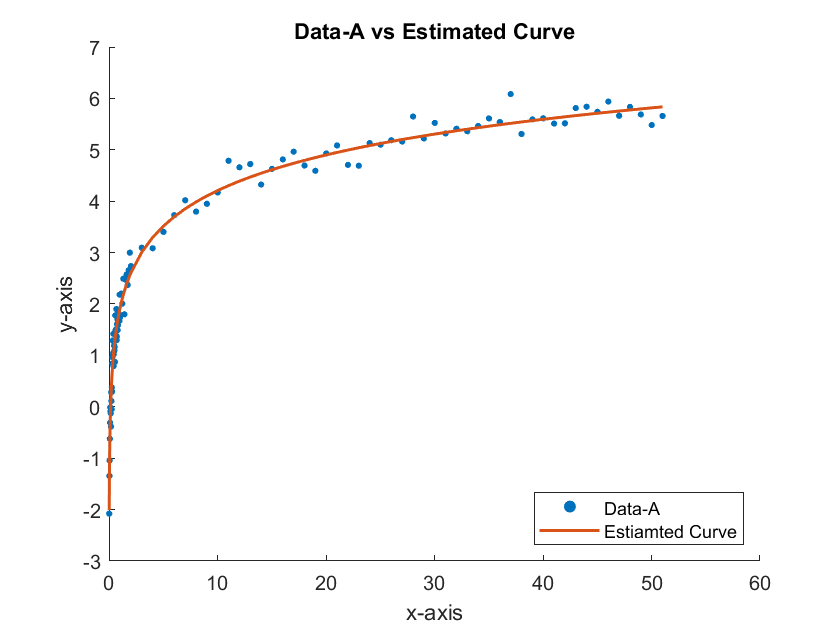

% Plotting the data points and the curve
figure
scatter(Xa,Ya, 10, 'filled')
hold on
plot(Xa, log(an*Xa), LineWidth=1.5)
title('Data-A vs Estimated Curve')
legend('Data-A', 'Estiamted Curve', Location='southeast')
xlabel('x-axis')
ylabel('y-axis')
hold off

### Calculating the error using the error function '`E = (y - log(a*x))^2``

e=0;
for i = 1:1:length(Xa)
    e = e + (Ya(i) - log(an*Xa(i)))^2;
end 
fprintf('Error in the given model for data-A is: %f', e)

Error in the given model for data-A is: 4.929149

# Nonlinear Regression fit: `log-data-B`

%% Loading log-data-B
data_B = importdata('log-data-B.txt');
Xb = data_B(:,1);
Yb = data_B(:,2);

#### Guess-1: Taking initial value of `a` = 0.5

%% Initial guess
a0 = 0.5;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xb)
        sum_fa = sum_fa + (-(2*(Yb(i) - log(a0*Xb(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yb(i) - log(a0*Xb(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 1.899612e+01

Total number of iterations until convergence: 12

#### Guess-2: Taking initial value of `a` = 1.2

%% Initial guess
a0 = 1.2;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xb)
        sum_fa = sum_fa + (-(2*(Yb(i) - log(a0*Xb(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yb(i) - log(a0*Xb(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 1.899612e+01

Total number of iterations until convergence: 11

#### Guess-3: Taking initial value of `a` = 2.3

%% Initial guess
a0 = 2.3;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xb)
        sum_fa = sum_fa + (-(2*(Yb(i) - log(a0*Xb(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yb(i) - log(a0*Xb(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 1.899612e+01

Total number of iterations until convergence: 10

#### Guess-4: Taking initial value of `a` = 4.5

%% Initial guess
a0 = 4.5;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xb)
        sum_fa = sum_fa + (-(2*(Yb(i) - log(a0*Xb(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yb(i) - log(a0*Xb(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 1.899612e+01

Total number of iterations until convergence: 8

### Plotting the model and the data points in log-data-B

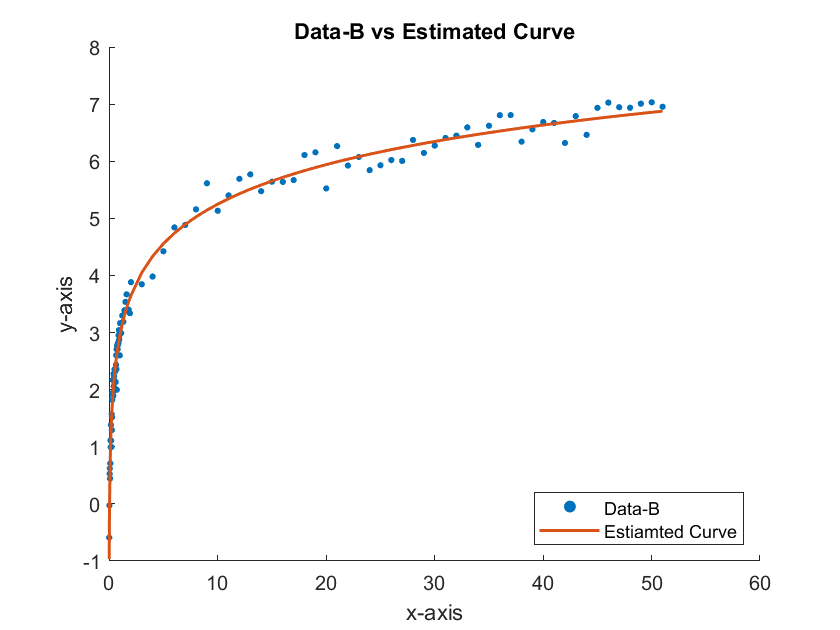

figure
scatter(Xb,Yb, 10, 'filled')
hold on
plot(Xb, log(an*Xb), LineWidth=1.5)
title('Data-B vs Estimated Curve')
legend('Data-B', 'Estiamted Curve', Location='southeast')
xlabel('x-axis')
ylabel('y-axis')
hold off

### Calculating the error using the error function '`E = (y - log(a*x))^2``

e=0;
for i = 1:1:length(Xb)
    e = e + (Yb(i) - log(an*Xb(i)))^2;
end 
fprintf('Error in the given model for data-B is: %f', e)

Error in the given model for data-B is: 4.286344

# Nonlinear Regression fit: `log-data-C`

%% Loading log-data-C
data_C = importdata('log-data-C.txt');
Xc = data_C(:,1);
Yc = data_C(:,2);

#### Guess-1: Taking initial value of `a` = 1.2

%% Initial guess
a0 = 1.2;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xc)
        sum_fa = sum_fa + (-(2*(Yc(i) - log(a0*Xc(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yc(i) - log(a0*Xc(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

% Checking if the estimated `a` is a valid number
if isinteger(an) == false
    fprintf('`a` is not a valid number, try a different guess!')
end

`a` is not a valid number, try a different guess!

#### Guess-2: Taking initial value of `a` = 0.8

%% Initial guess
a0 = 0.8;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xc)
        sum_fa = sum_fa + (-(2*(Yc(i) - log(a0*Xc(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yc(i) - log(a0*Xc(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

% Checking if the estimated `a` is a valid number
if isinteger(an) == false
    fprintf('`a` is not a valid number, try a different guess!')
end

`a` is not a valid number, try a different guess!

#### Guess-3: Taking initial value of `a` = 0.3

%% Initial guess
a0 = 0.3;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xc)
        sum_fa = sum_fa + (-(2*(Yc(i) - log(a0*Xc(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yc(i) - log(a0*Xc(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 2.899978e-01

Total number of iterations until convergence: 4

#### Guess-4: Taking initial value of `a` = 0.15

%% Initial guess
a0 = 0.15;

%% Performing iterations
iterations = 0;
for n = [1:5000]
    sum_fa = 0;
    sum_dfa = 0;
    for i = 1:1:length(Xc)
        sum_fa = sum_fa + (-(2*(Yc(i) - log(a0*Xc(i))))/a0);
        sum_dfa = sum_dfa + (2/a0^2 + (2*(Yc(i) - log(a0*Xc(i))))/a0^2);
    end 
    an = a0 - (sum_fa/sum_dfa);
    iterations = iterations+1;
    if abs(an-a0) <0.000001
        fprintf('Final value of `a` after convergence: %d', an);
        fprintf('Total number of iterations until convergence: %d', iterations);
        break
    end
    a0 = an;
end

Final value of `a` after convergence: 2.899978e-01

Total number of iterations until convergence: 6

### Plotting the model and the data points in log-data-C

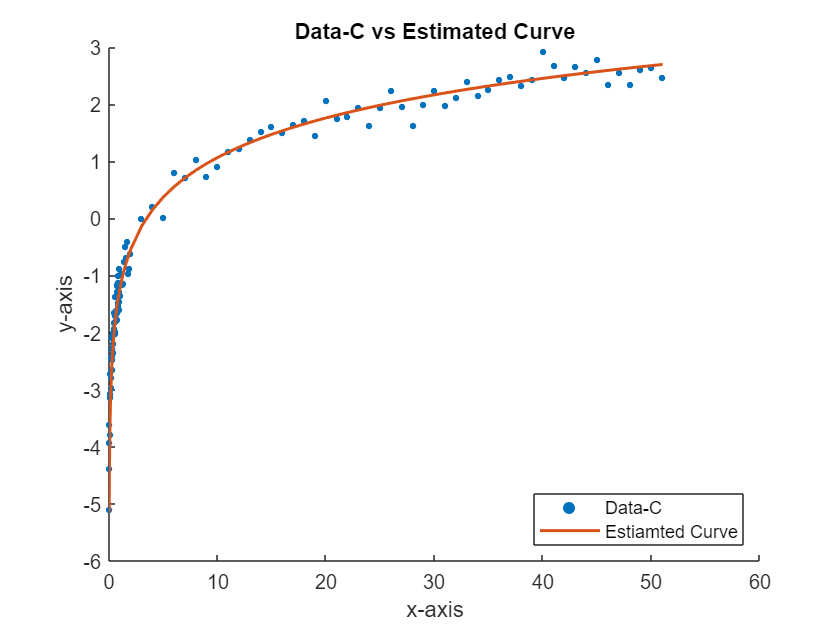

figure
scatter(Xc,Yc, 10, 'filled')
hold on
plot(Xc, log(an*Xc), LineWidth=1.5)
title('Data-C vs Estimated Curve')
legend('Data-C', 'Estiamted Curve', Location='southeast')
xlabel('x-axis')
ylabel('y-axis')
hold off

### Calculating the error using the error function '`E = (y - log(a*x))^2``

e=0;
for i = 1:1:length(Xc)
    e = e + (Yc(i) - log(an*Xc(i)))^2;
end 
fprintf('Error in the given model for data-C is: %f', e)

Error in the given model for data-C is: 3.814397